% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.

% TEST_GPU_implementation_regression_yacht_full_rank6k.mlx
% Load a saved trained network and evaluate held-out yacht full-rank 6k regression performance.
% This script does not train. Run the matching training script first, then choose which saved backend to load below.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved Network ----------------
% This file is created by the matching train script. It stores the training options
% and the best trained bias vector. The test action reconstructs deterministic
% weights from saved options, restores best.B, and evaluates the held-out split.
test_seeds = [1]; % Trained initialization seed(s) to evaluate.
diagnostic_seed_index = 1; % Spike diagnostics use one representative seed to keep live plots readable.
test_backend = 'gpu'; % This script evaluates with the GPU implementation.
trained_model_backend = 'gpu'; % Use the model family produced by the matching training script.
[model_files, model_file, trained_model_backend] = snn_resolve_seed_model_files(repo_root, 'regression_yacht_full_rank6k', test_backend, test_seeds, diagnostic_seed_index, trained_model_backend);
save_diagnostic_files = false;  % set true to write diagnostic artifacts as well as displaying inline
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', sprintf('regression_yacht_full_rank6k_trained_%s_test_gpu', trained_model_backend));
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
missing_model_files = model_files(cellfun(@(f) exist(f, 'file') ~= 2, model_files));
if ~isempty(missing_model_files)
    error('Saved model(s) not found. Run the matching training script for all requested seeds first. First missing file: %s', missing_model_files{1});
end

%% ---------------- Evaluation Overrides ----------------
% model_file is required. batch_size can be lowered if GPU memory is limited.
% Other fields placed in opts override the saved training options for evaluation only.
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file; % Representative seed retained for diagnostics and legacy plot helpers.
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
% result.test.loss is average held-out loss.
% result.test.metric is Pearson r for the held-out split.
result = snn_primary_api('test_static', 'regression', test_backend, opts);

[SEED AUDIT] Single seed tested; no pairwise network-difference check required.
Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\regression_yacht_full_rank6k_gpu_test_analysis_20260721_152332_668.mat


fprintf('Testing with %s backend; loaded %s-trained networks for seeds [%s]. Diagnostic seed file:\n%s\n', test_backend, trained_model_backend, num2str(test_seeds), model_file);

Testing with gpu backend; loaded gpu-trained networks for seeds [1]. Diagnostic seed file:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\regression_yacht_full_rank6k_gpu_primary_seed001.mat


    Seed     Loss       RMSE     PearsonR
    ____    _______    ______    ________

     1      0.14293    8.7791    0.78274 



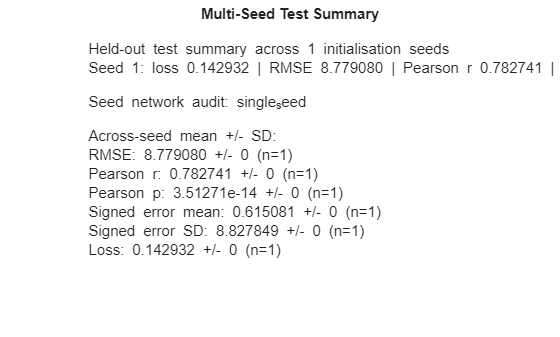

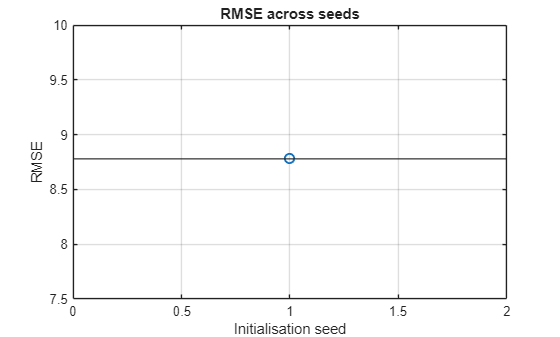

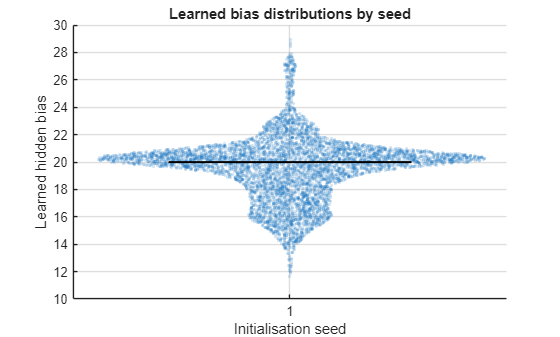

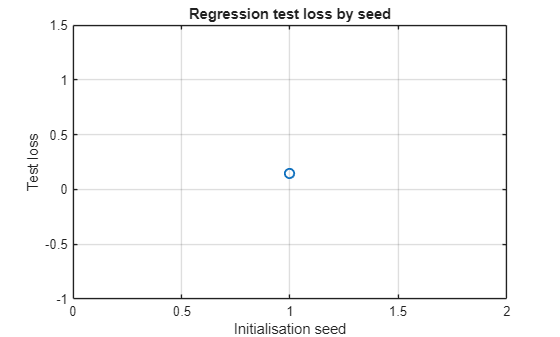

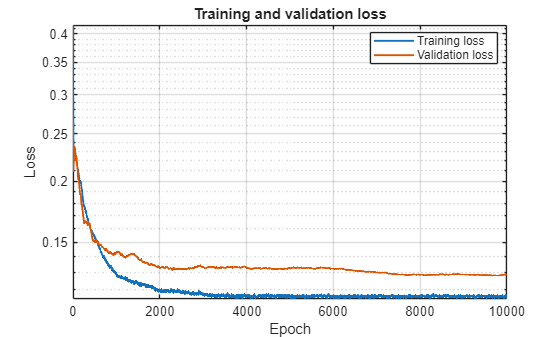

snn_plot_test_result(result);


=== Spiking Diagnostics: yacht_test_regression ===
Samples: 8 | Neurons: 6000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 2.86951 Hz | median 2.08333 Hz | 95th percentile 8.75 Hz
Active neurons: 4777 / 6000 (79.62%)
Silent neurons: 1223 / 6000 (20.38%)
Mean population rate by sample: 2.86951 Hz/neuron
Mean active neurons by sample: 43.95% | silent 56.05%
Total within-sample ISIs counted: 20227
Median per-neuron mean inverse-ISI rate: 9.44681 Hz


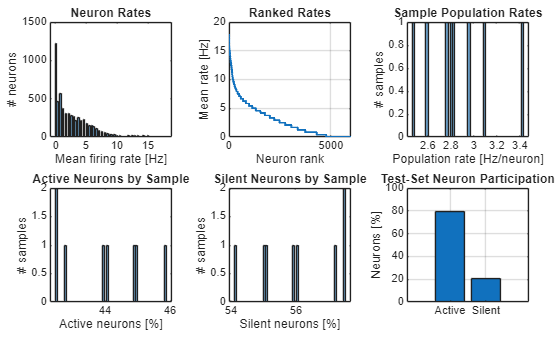

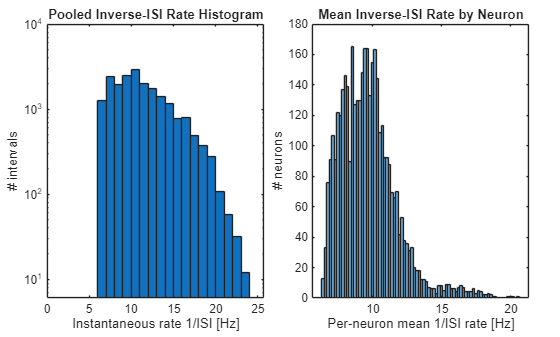

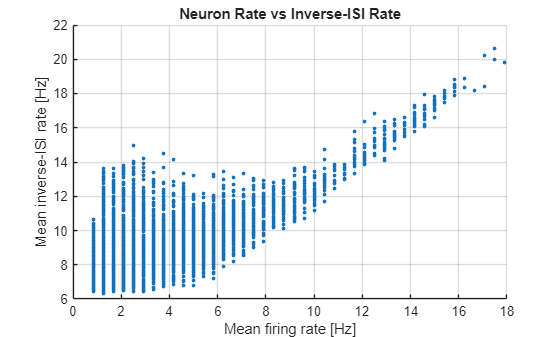

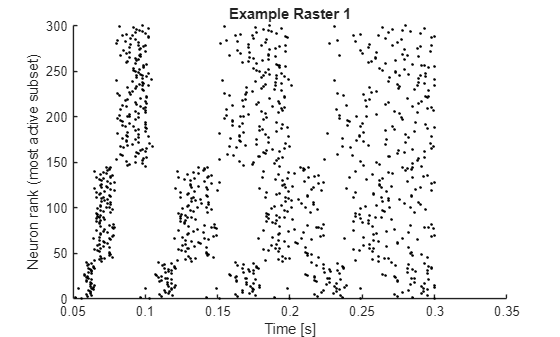

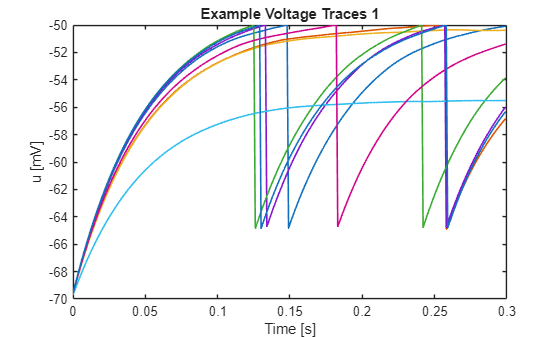

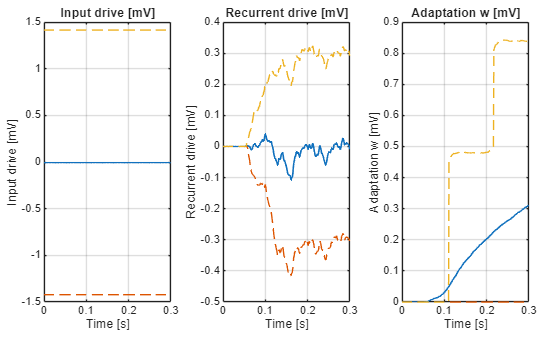

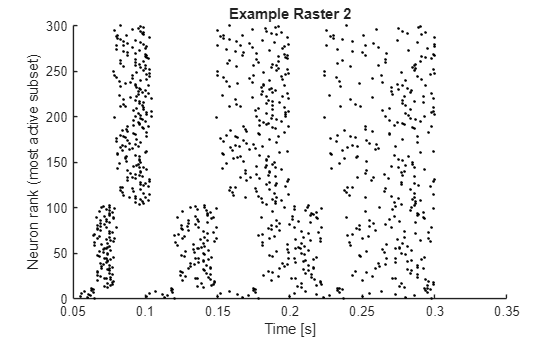

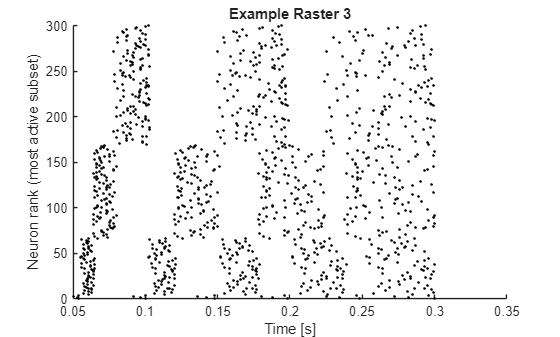

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
% These diagnostics replay the saved trained network through the CPU reference
% to produce spike rasters, firing-rate summaries, ISI histograms, voltage traces,
% input/recurrent/adaptation current summaries. By default they display inline only.
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_static', 'regression', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 79.62%% (4777/6000); silent neurons: 20.38%% (1223/6000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 43.95%%; silent neurons: 56.05%%.


fprintf('Loaded trained network from:\n%s\n', model_file);

Loaded trained network from:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\regression_yacht_full_rank6k_gpu_primary_seed001.mat


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

          loss: 0.1429
        metric: 0.7827
         count: 63
             Z: [-0.7626 0.0859 -1.2486 -0.0117 -0.3968 -0.2946 -0.6598 -0.4273 -1.3168 1.1185 -0.3043 0.9437 1.0018 0.7384 -1.2961 0.9313 -1.1789 0.6607 0.2107 -0.1573 -0.9755 -0.9277 0.9509 -1.0796 -0.6933 -1.1056 -0.3699 -0.5128 … ] (1×63 single)
             Y: [-0.6447 -0.4260 -0.7007 -0.4638 -0.6465 -0.6075 -0.6782 -0.6526 -0.7135 1.2146 -0.5479 1.2743 0.6836 -0.2823 -0.7105 0.5228 -0.7056 -0.0162 -0.4912 -0.5606 -0.6678 -0.7050 1.8237 -0.6916 -0.6246 -0.7196 -0.6410 -0.5686 … ] (1×63 single)
    regression: [1×1 struct]

